 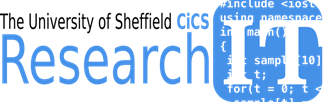

# **Exercises for Data Visualisation with Matlab**

**Obtaining the Examples**

- The course examples are available under the CIC6007 course on the online learning system, see matlab examples under the course content

The matlab examples zip file can also be downloaded from

     [http://rcg.group.shef.ac.uk/courses/cic6007 /matlab_examples.zip](http://rcg.group.shef.ac.uk/courses/cic6007 /matlab_examples.zip)

Iceberg users may extract the examples from a tgz archive in the directory  /usr/local/courses on iceberg.

On ShARC, use cd to change directory to a working directory of your choice then use the cp and tar commands to obtain and extract the examples.

The required commands are

 cd ~/myworkingdirectory

 tar –zxvf /usr/local/courses/matlab_examples.tgz

# Practice Session 1

## Exercises 6 : Importing Data and Plotting in MATLAB

In the exercise directory you will find a data file named *field.dat* .    

6.1  Read it into MATLAB and store columns 1 to 3 of the data as; temperature, pressure and density respectively

%Use Import Data from the home bar  or  Start -> Import Wizard .  This should read all the data into a variable called FIELD. Then;   temp = FIELD(:,1) ; 
%pres = FIELD(:,2) ;  dens = FIELD(:,3);
field=readtable('field.dat');
[frows,fcols]=size(field)
temp=field.Var1
pres=field.Var2
dens=field.Var3


6.2  Using the PLOT command plot temperature variation

6.3  Using the PLOT command plot pressure variation

6.4  By making use of the HOLD command, plot both temperature and pressure in the same graph.

plot(temp) ;
plot(pres) ;
hold on ; plot(temp , 'g' ) ;



6.5   Fit a 5th degree polynomial to the data, display the equation on the graph and save the fitting parameters into the workspace via the Tools > Basic Fitting menu of the Figure window

%for help use 
%e.g. use [p,S] = polyfit(x,y,n)
help polyfit
[p,S] = polyfit(1:frows,temp,5)

6.6 Compute the max, min, mean and median values of the plot variables

6.7  Plot the mean value of y as a line on the current plot ( Hint: contract two end points of a line using values from the basic statistics and use them in a call to line command  but don’t forget to use the hold command first)

6.8  Using the edit-plot icon from the figure window toolbar edit this graph to change the colour of the mean-value line and the legend for it.

% eg. use
field=temp;
y = [mean(field),median(field),max(xfield),min(field)]

6.9  Using the SUBPLOT command. Plot three separate plots of all three variables on the same screen. Experiment with editing other aspects of the plot.

subplot(2,2,1); plot(temp)
subplot(2,2,2); plot(dens)
subplot(2,2,3); plot(pres)

## Exercise 2

Basic graphics



load('..\data\trend.txt')


% TASK 1 - edit trend.txt  ( by double clicking on it in matlab folder to view )
%    to see what it contains.
%                  
% It is possible to read well constracted data files such as trend.txt
% into matlab by using the LOAD command.
% type:  DOC LOAD   and investigate help on using the LOAD command.
%  TASK 2- Read in this trend.txt into MATLAB using the LOAD command.
%
%  TASK 3 -Save each column as a seperate variable by using vector
%           assignments calling them Y1  and Y2 
%  TASK 4: Plot Y1  using the PLOT command.
%
% TASK 5 : Use the import data wizard to read this same data. 



% TUTORIAL 3                                 By Deniz Savas, February 2016
% Having read into MATLAB the trend data by running tutorial 1 or 2
% perform the following tasks to plot the data.
% 
% Given that y1 is the first column of data 
%            y2 is the second column of data
%            Y= [y1 , y2 ] 
%%
% TASK 1 : Plotting
% Constract a vector called x  that is the same length and shape as y1 
%  and contains numbers from 1 to 100 ( or scaled by 100 so that it runs
%  from 0.01 to 1.00
% HINT you can either use notation the : notation. I.e start:interval:stop 
%  				or  LINSPACE function .
% 
% Plot y1 against x 
% HINT: type DOC PLOT  to find out about the use of plot command. 

%%
% TASK 2: Plotting multiple curves in one graph. 
% Open another graphics window. HINT: use FIGURE command.
%  Plot y1 against x and y2 against x on the same plot using a single PLOT 
%  command. 

%%
% TASK 3: Overlaying Plots
%  
%  Plot y1 against x and y2 against x on the same plot  
%   but this time use two PLOT commands.
%  HINT: use HOLD command.

%%
% TASK 4 :  Using subplots 
% Split your graphics window into two sections and plot y1 in one section 
% and scattered values of y1 in another section.
% HINT: Use SUBPLOT and SCATTER commands. 
% 

%% 
% TASK 5 : Properties of Graphical objects
%  Draw a scatter plot of y1 
%  Fill the data markers with red colour.
%  HINT: Save the handle of the scatter plot while creating it.
%        [ i.e.   s1= scatter( ....     ]
% and then type  s1 to see its common properties names and values.
%
% Redefine the MarkerFaceCOlor property of the plot to be red ( i.e. 'r' ) 
% HINT : assign a value to  object.PropertyName
%
%%
% TASK 6 : Decorating a graph
% 
% Use the commands  TITLE , XLABEL , YLABEL  to label the graph.
% Use the GTEXT command to add the anotation 'Turning Point' to a suitable
% location on the graph. 

%%
% TASK 7 : Manipulating the axis characteristics 
% Using the XLIM and YLIM commands or the AXIS command adjust the plotting 
% range and observe the graph. 
% You can add grid lines to your graph using the GRID command. 
% Experiment with grid on/off , axis on/off commands.

%%
% TASK 8 : Using the axes handle
% gca returns the handle of the currently used axes.
% Having aquired the handle of the current axes we can interrogate and also
% change its properties via the get and set commands respectively
get(gca ) 
% Use the set command to change the range of the y axis limits by filling
% in the missing two parameters of the following set command;
% set ( gca , '......' , '.......' ) 






## Exercise 3

Create a filled scatter plot that plots the `data.Windspeed`values at sea, i.e., values not on land (`~onland`), along the x-axis and the corresponding `data.Pressure` values along the y-axis. Use circular markers with blue color. Make sure the marker faces are semitransparent and have blue color.

% create a new variable named data.HurrCat that contains the 
% hurricane category of the observation based on data.Windspeed.
data = readtable('..\data\hurricaneData1990s-v2.txt','HeaderLines',5);

%if any windspeeds are NaN set to zero
idwindnan = find(isnan(data.Windspeed));
data.Windspeed(idwindnan)=0;

sz=size(data);
a=data.Country;
for i=1:sz(1)
  if isequal(a{i},'N/A' )
      data.Location{i} = 'Sea';
      onland(i)=0;
  else
      data.Location{i} = 'Land';
      onland(i)=1;
  end
end

data.Location;

figure
hold on
scatter(data.Windspeed(~onland),data.Pressure(~onland),'b','filled','MarkerFaceAlpha',0.5)
scatter(data.Windspeed(onland==1),data.Pressure(onland==1),'r','filled','MarkerFaceAlpha',0.5)
hold off

Change the x-axis limits to go from 15 to 60 and add minor grid lines to the scatter plot.

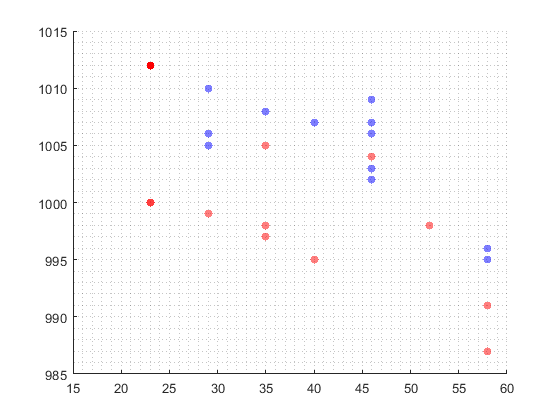

xlim([15 60])
grid('minor') %add minor states

Plotting bargraphs and binning data and using discretization



% Find index of on-land and on-sea observation index
SSscale = [0 39 74 96 111 130 157 Inf];
catnames = {'TD','TS','1','2','3','4','5'};
data.HurrCat = discretize(data.Windspeed,SSscale,'Categorical',catnames)

data = 51×7 table
    Number         Timestamp              Country        Windspeed    Pressure    Location    HurrCat
    ______    ____________________    _______________    _________    ________    ________    _______

    1         29-Jun-1991 12:00:00    'N/A'               23          1012        'Sea'       TD     
    1         29-Jun-1991 18:00:00    'N/A'               23          1012        'Sea'       TD     
    1         30-Jun-1991 00:00:00    'N/A'                0          1012        'Sea'       TD     
    1         30-Jun-1991 06:00:00    'United States'     23          1012        'Land'      TD     
    1         30-Jun-1991 12:00:00    'United States'     23          1012        'Land'      TD     
    1         30-Jun-1991 18:

windBinNo = discretize(data.Windspeed,SSscale);

sz=size(SSscale)

sz =      1     8


szw=size(windBinNo)

szw =     51     1


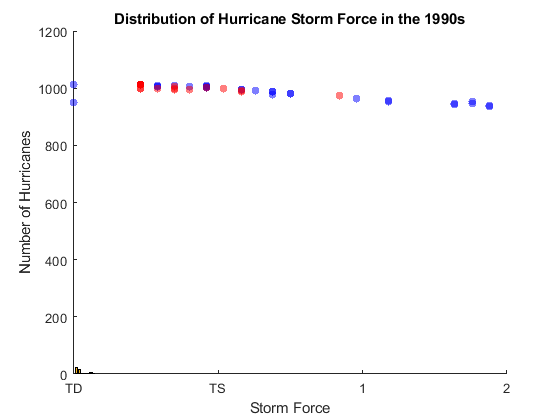

numwindbin=zeros(sz(2)-1,1);
for i=1:szw(1)
    windbin=windBinNo(i);
    numwindbin(windbin)=numwindbin(windbin)+1;
end
bar(numwindbin);
title('Distribution of Hurricane Storm Force in the 1990s');
xlabel('Storm Force');
ylabel('Number of Hurricanes');
set(gca,'XTickLabel',catnames);

Exercise to Load data and 

The file 'fuelEconomy.txt' contains fuel economy data for different models of cars (you can use the command `edit` `fuelEconomy.txt` to examine its contents). 

The goal of this exercise is to divide the combined miles per gallon data into three classes and create a scatter plot of city and highway miles per gallon like the one shown below.

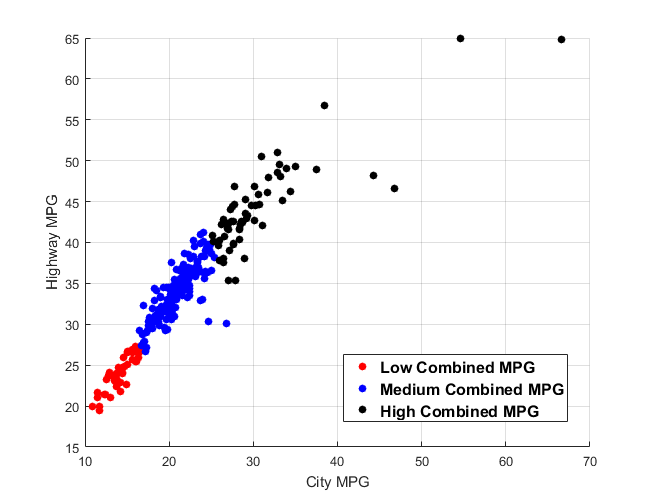

Follow the steps listed below:

Step 1 – Import the data into a table.

Step 2 – The variable `CombinedMPG` contains missing values represented by NaN. Remove the rows corresponding to these missing values from the imported table.

Step 3 – Discretize the `CombinedMPG` variable into three classes called 'Low', 'Medium', and 'High' using the bin edges 0, 20, 30, and 70 (values greater than or equal to 0 and less than 20 are classified as 'Low' and so on). Store the discretized result in a variable named `MPGClass`.

Step 4 – Create a scatter plot with `CityMPG` on the x-axis and `HighwayMPG` on the y-axis. Observations with 'Low' combined MPG should be colored red (`'r'`), 'Medium' should be blue (`'b'`), and 'High' should be 'black' (`'k'`).

% Read data
data=readtable('../data/fuelEconomy.txt')

data = 386×7 table
        Class             Make                    Model              NumCyl    CityMPG    HighwayMPG    CombinedMPG
    _____________    _______________    _________________________    ______    _______    __________    ___________

    'TWO SEATERS'    'ASTON MARTIN'     'DBS COUPE'                  12          14.4       24.7        17.726     
    'TWO SEATERS'    'ASTON MARTIN'     'V8 VANTAGE'                  8        15.938     26.855        19.506     
    'TWO SEATERS'    'AUDI'             'R8'                          8            11     25.045        18.628     
    'TWO SEATERS'    'AUDI'             'TT ROADSTER'                 4          28.5       42.2        33.376     
    'TWO SEATERS'    'AUDI'             'TT RO

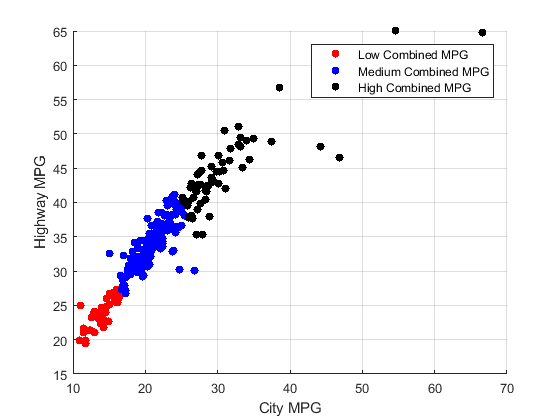


% Identify the rows containing NaN values and remove them
nanIdx = ismissing(data.CombinedMPG);
data(nanIdx,:) = [];

% Discretize Combined MPG
MPGClass = discretize(data.CombinedMPG,[0 20 30 70],{'Low' 'Medium' 'High'});

% Optional - Convert the class into a categorical array
MPGClass = categorical(MPGClass);

% Extract observations for various classes and plot them
scatter(data.CityMPG(MPGClass == 'Low'),data.HighwayMPG(MPGClass == 'Low'),...
'r','filled')
hold on
scatter(data.CityMPG(MPGClass == 'Medium'),data.HighwayMPG(MPGClass == 'Medium'),...
'b','filled')
hold on
scatter(data.CityMPG(MPGClass == 'High'),data.HighwayMPG(MPGClass == 'High'),...
'k','filled')
hold off

grid on
xlabel('City MPG')
ylabel('Highway MPG')
legend('Low Combined MPG','Medium Combined MPG','High Combined MPG');